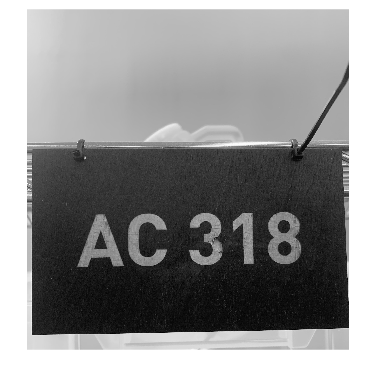

image = imread("AC 318.jpg");
%Preprocessing Steps
gray_image = im2gray(image); %Color to grayscale conversion
imshow(gray_image)

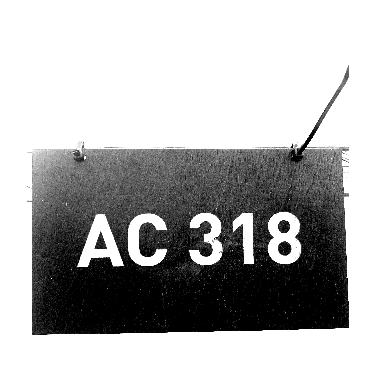


adjusted_image = imadjust(gray_image, [0.1, 0.4]); %Contrast adjustment
imshow(adjusted_image)

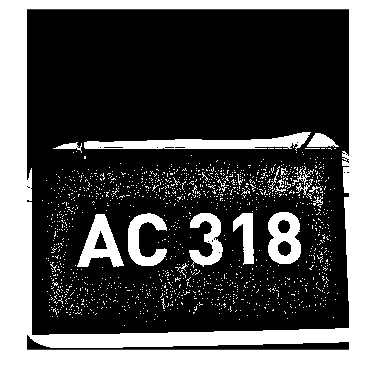

binarized_image = imbinarize(adjusted_image, adaptthresh(adjusted_image, 0.4)); %Conversion to binary image
imshow(binarized_image)

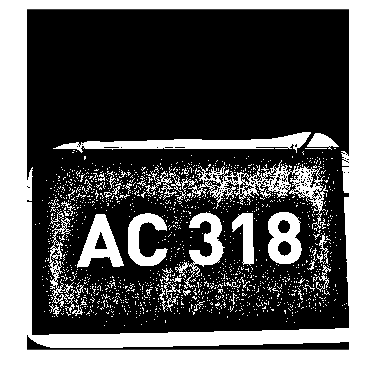


dilated_image = imdilate(binarized_image, strel("line", 4, 0)); %Dilation
imshow(dilated_image)

%imageRegionAnalyzer(dilated_image) %Use to determine size of regions

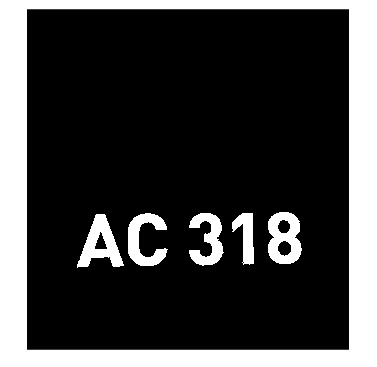

%bwpropfilt is noise filtering
%bwpropfilt only accepts struct objs
CC = bwconncomp(dilated_image);  %convert image to struct
CC = bwpropfilt(CC,'Perimeter',[1200, 2500]); %only keep objects with a perimeter between 1200 and 2500 pixels
CC = bwpropfilt(CC,'Area',[50000 + eps(50000), Inf]); %only keep objects with an area greater than 50000 pixels
area_peri_filtered_image = cc2bw(CC); %convert struct back to image
imshow(area_peri_filtered_image)

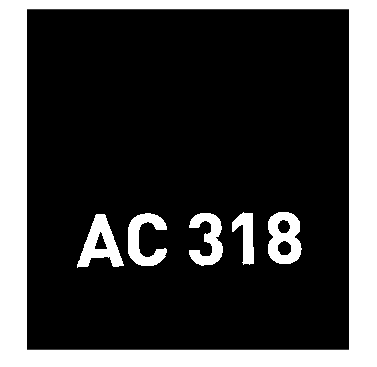

median_filtered_image = medfilt2(area_peri_filtered_image, [4 4]); %smoothing
imshow(median_filtered_image)

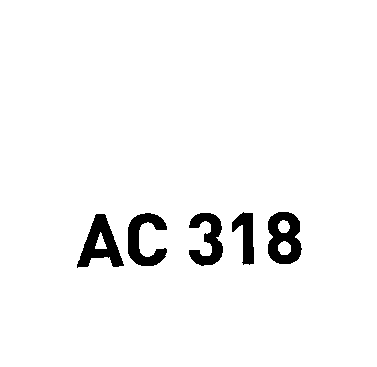

imcomplement_image = imcomplement(median_filtered_image); %color inversion
imshow(imcomplement_image)

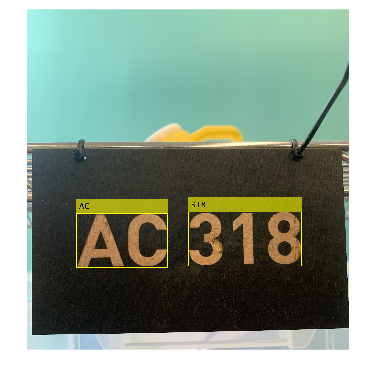

%OCR steps
output = ocr(area_peri_filtered_image,LayoutAnalysis="block");
Iocr = insertObjectAnnotation(image,"rectangle", ...
            output.WordBoundingBoxes,output.Words,LineWidth=5,FontSize=72);
figure
imshow(Iocr)

OCR_result = output.Text

OCR_result =     'AC 318
     
     '


%Post-process
%Isolate numbers
% Use regexp to find all sequences of digits
isolated_number = regexp(OCR_result, '\d+', 'match');
    
    % Convert the matched strings to numbers
number_input = str2double(isolated_number);

%Convert numbers to spelled out version
function words = numberToWords(num)
    % This function converts a number to its spelled-out text equivalent
    % Input: num - a number (can be negative)
    % Output: words - string containing the spelled-out text

    % Arrays for words
    ones = {'', 'one', 'two', 'three', 'four', 'five', 'six', 'seven', 'eight', 'nine', ...
           'ten', 'eleven', 'twelve', 'thirteen', 'fourteen', 'fifteen', 'sixteen', ...
           'seventeen', 'eighteen', 'nineteen'};
    tens = {'', '', 'twenty', 'thirty', 'forty', 'fifty', 'sixty', 'seventy', 'eighty', 'ninety'};
    scales = {'', 'thousand', 'million', 'billion', 'trillion', 'quadrillion', 'quintillion'};
    
    % Handle special cases
    if num == 0
        words = 'zero';
        return;
    end
    
    if num < 0
        words = ['negative ' numberToWords(abs(num))];
        return;
    end
    
    words = '';
    scaleIndex = 1;
    
    % Process number in chunks of 3 digits
    while num > 0
        chunk = mod(num, 1000);
        if chunk ~= 0
            chunkWords = convertChunkToWords(chunk, ones, tens);
            
            if isempty(words)
                words = [chunkWords ' ' scales{scaleIndex}];
            else
                words = [chunkWords ' ' scales{scaleIndex} ' ' words];
            end
        end
        
        num = floor(num / 1000);
        scaleIndex = scaleIndex + 1;
    end
    
    words = strtrim(words);
end

function words = convertChunkToWords(chunk, ones, tens)
    % Helper function to convert a chunk (1-999) to words
    words = '';
    
    % Handle hundreds
    if chunk >= 100
        words = [ones{floor(chunk/100) + 1} ' hundred'];
        chunk = mod(chunk, 100);
        if chunk ~= 0
            words = [words ' '];
        end
    end
    
    % Handle tens and ones
    if chunk < 20
        words = [words ones{chunk + 1}];
    else
        tenPart = [tens{floor(chunk/10) + 1}];
        onePart = ones{mod(chunk, 10) + 1};
        
        if mod(chunk, 10) ~= 0
            words = [words tenPart ' ' onePart];
        else
            words = [words tenPart];
        end
    end
end

%Get output
spelledout_number = numberToWords(number_input)

spelledout_number = 'three hundred eighteen'

%add spelled out version back to string
speech_input = append("AC" + " " + spelledout_number)

speech_input = "AC three hundred eighteen"

%TTS 
[speech, fs] = text2speech(speech_input)

Error using speechClient>iCheckSupportPkgInstalled (line 75)
You need Audio Toolbox Interface for SpeechBrain and Torchaudio Libraries before you can use this feature. Open Add-On Explorer to install the required support package.

Error in speechClient (line 45)
 

sound(speech)